%read MNIST data and save them to mat file
imgFile = 'train-images.idx3-ubyte';
labelFile = 'train-labels.idx1-ubyte';
readDigits = 60000;
offset = 0;
[imgs_train, labels_train] = readMNIST(imgFile, labelFile, readDigits, offset);
labels_train = categorical(labels_train);
%
imgFile = 't10k-images.idx3-ubyte';
labelFile = 't10k-labels.idx1-ubyte';
readDigits = 10000;
offset = 0;
[imgs_test, labels_test] = readMNIST(imgFile, labelFile, readDigits, offset);
labels_test = categorical(labels_test);
save('mnist.mat','imgs_test','imgs_train','labels_test','labels_train');



close all
%load data
data = load("mnist.mat");
imgs_train=data.imgs_train;
labels_train=data.labels_train;
imgs_test = data.imgs_test;
labels_test=data.labels_test;

[d1,d2,ntrain] = size(imgs_train);
Xtrain = zeros(d1,d2,1,ntrain);
for j = 1:ntrain
    Xtrain(:,:,1,j) = imgs_train(:,:,j);
end

[d1,d2,ntest] = size(imgs_test);
Xtest = zeros(d1,d2,1,ntest);
for j = 1:ntest
    Xtest(:,:,1,j) = imgs_test(:,:,j);
end


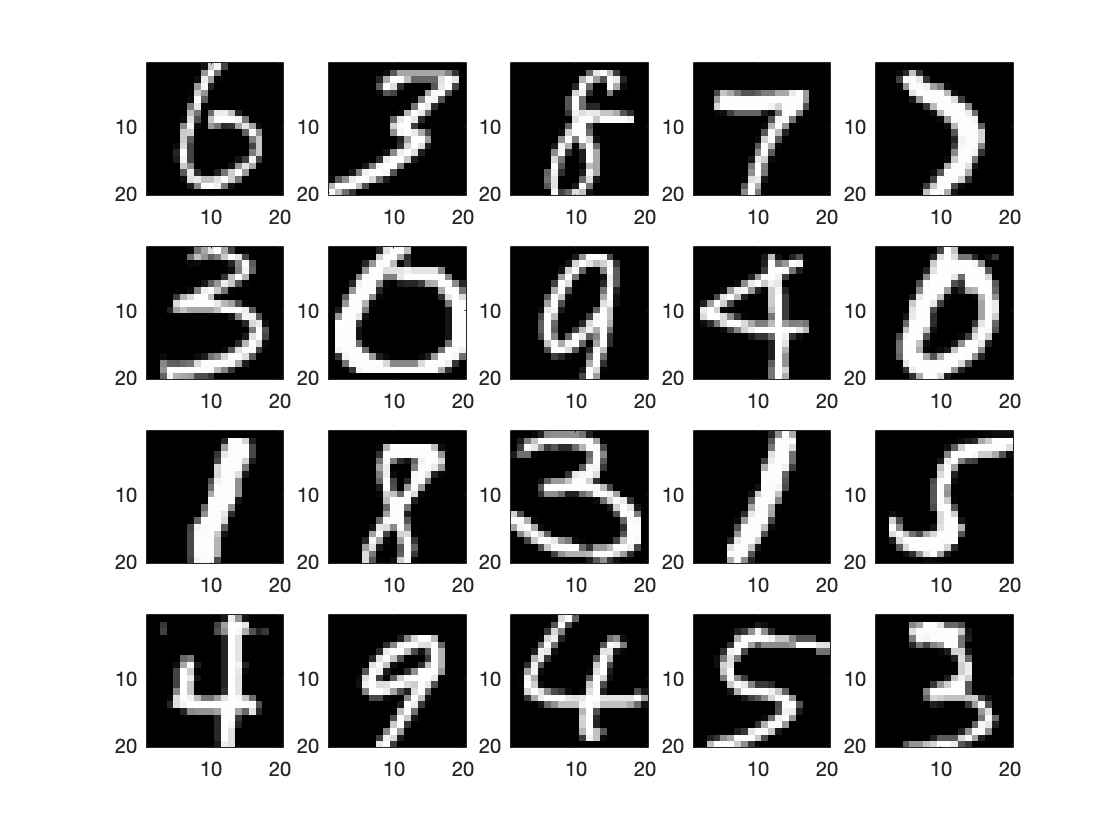

figure
colormap gray
perm= randperm(ntest,20);
for i=1:20
    subplot(4,5,i);
    imagesc(imgs_test(:,:,perm(i)));
end

layers = [ ...
    imageInputLayer([d1,d2,1])
    convolution2dLayer(5,16, 'Padding',1)
    reluLayer
    batchNormalizationLayer
    maxPooling2dLayer(2,'Stride',2)
    groupedConvolution2dLayer(3,24,2,'Padding',"same")
    reluLayer
%     crossChannelNormalizationLayer(5)
%     maxPooling2dLayer(2,'Stride',2)
%     convolution2dLayer(3,32,'Padding',1)
%     reluLayer
%     groupedConvolution2dLayer(3,36,2,'Padding',"same")
%     reluLayer
%     groupedConvolution2dLayer(3,36,2,'Padding',"same")
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
%     fullyConnectedLayer(512)
%     reluLayer
%     dropoutLayer(0.5)
    fullyConnectedLayer(512)
    reluLayer
    dropoutLayer(0.5)
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-3, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(Xtrain,labels_train,layers,options);

Label_test_pred = classify(net, Xtest);
accuracy = sum(Label_test_pred == labels_test)/numel(labels_test)

accuracy = 0.9880